POLAR COORDINATES UNICYCLE

close all
clear all

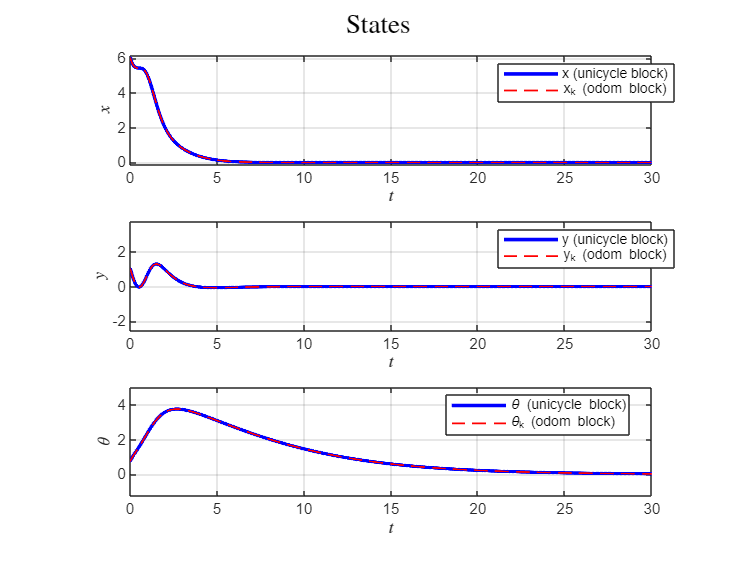

a = 5;
xi = a + 1;
yi = 1;
thetai = pi/4;
qi = [xi, yi, thetai]';
qf = [0, 0, 0]';
Ts = 0.01;

k1 = 1;
k2 = 1;
k3 = 0.15;

out = sim('ex4.slx');

state = out.state.data;
statek = out.statek.data;
polar_state = out.polar_state.data;
vk = out.vk.data;
wk = out.wk.data;
vk1 = out.vk1.data;
wk1 = out.wk1.data;
xk = out.xk.data;
yk = out.yk.data;
thetak = out.thetak.data;
x = out.xk.data;
y = out.yk.data;
theta = out.thetak.data;
ex = out.ex.data;
ey = out.ey.data;
etheta = out.etheta.data;
e = out.e.data;
t = out.x.time;


figure
subplot(3,1,1)
plot(t, x,'b', 'LineWidth', 2, 'DisplayName', 'x (unicycle block)'); hold on;
plot(t, xk,'r--', 'LineWidth', 1, 'DisplayName', 'x_k (odom block)');
xlabel('$t$','Interpreter','latex')
ylabel('$x$','Interpreter','latex')
grid on
axis equal
xlim([0, 30]);
legend('Location','best')
subplot(3,1,2)
plot(t, y,'b', 'LineWidth', 2, 'DisplayName', 'y (unicycle block)'); hold on;
plot(t, yk,'r--', 'LineWidth', 1, 'DisplayName', 'y_k (odom block)');
xlabel('$t$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
xlim([0, 30]);
legend('Location','best')
subplot(3,1,3)
plot(t, theta, 'b', 'LineWidth', 2, 'DisplayName', '\theta (unicycle block)'); hold on;
plot(t, thetak,'r--', 'LineWidth', 1, 'DisplayName', '\theta_k (odom block)');
xlabel('$t$','Interpreter','latex')
ylabel('$\theta$','Interpreter','latex')
grid on
axis equal
xlim([0, 30]);
legend('Location','best')
sgtitle('States','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'state_uni_vs_odom_es4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

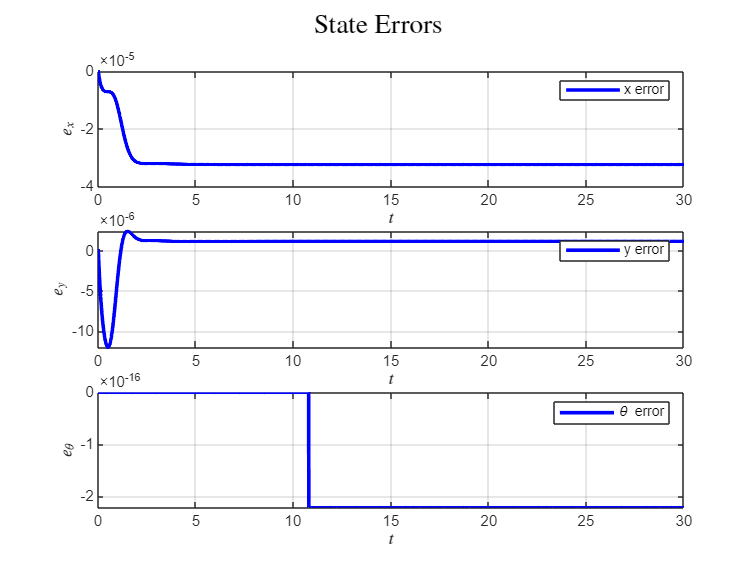


figure
subplot(3,1,1)
plot(t, ex,'b', 'LineWidth', 2, 'DisplayName', 'x error'); 
xlabel('$t$','Interpreter','latex')
ylabel('$e_x$','Interpreter','latex')
grid on
xlim([0, 30]);
legend
subplot(3,1,2)
plot(t, ey,'b', 'LineWidth', 2, 'DisplayName', 'y error'); 
xlabel('$t$','Interpreter','latex')
ylabel('$e_y$','Interpreter','latex')
grid on
xlim([0, 30]);
legend
subplot(3,1,3)
plot(t, etheta,'b', 'LineWidth', 2, 'DisplayName', '\theta error'); 
xlabel('$t$','Interpreter','latex')
ylabel('$e_{\theta}$','Interpreter','latex')
grid on
legend
sgtitle('State Errors','Interpreter','latex')
xlim([0, 30]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'state_error_es4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

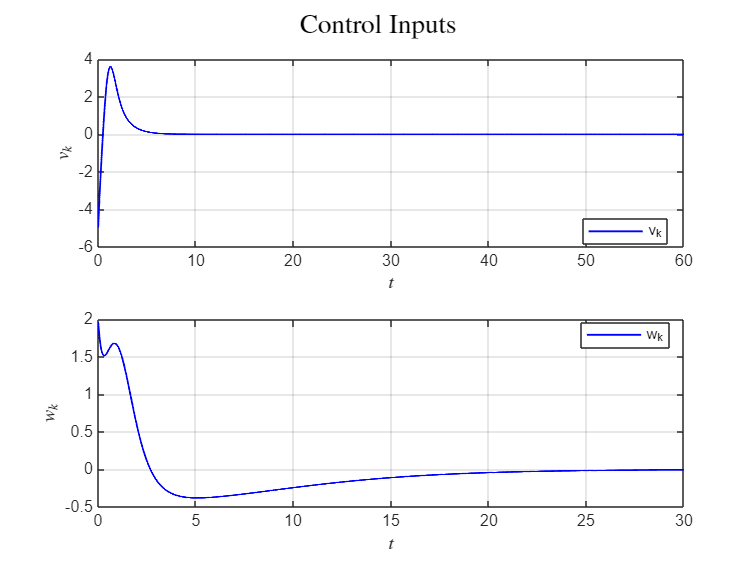

figure
subplot(2,1,1)
plot(t, vk1,'b', 'LineWidth', 1, 'DisplayName', 'v_k'); 
xlabel('$t$','Interpreter','latex')
ylabel('$v_k$','Interpreter','latex')
grid on
legend('Location','best')
subplot(2,1,2)
plot(t, wk1,'b', 'LineWidth', 1, 'DisplayName', 'w_k');
xlabel('$t$','Interpreter','latex')
ylabel('$w_k$','Interpreter','latex')
grid on
legend('Location','best')
sgtitle('Control Inputs','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
xlim([0, 30])
exportgraphics(gcf, 'control_inputs_es4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');